data = load("C:\Users\adi03\Downloads\departures_HW7.mat");
departures = data.departures

departures =     89
    85
    88
    71
    73
    87
    85
    77
    62
    59


% Index of depatures is days

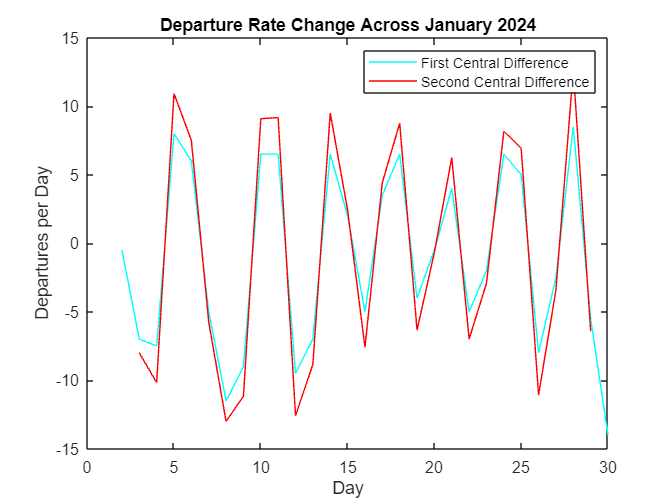

% Question 1
% a)
derivative1 = zeros(length(departures)-2, 1);

h = 1;
for i = 2:length(departures)-1
    derivative1(i-1) = (departures(i+1) - departures(i-1)) / (2*h);
end
% b)
derivative2 = zeros(length(departures)-4, 1);

for i = 3:length(departures)-2
    derivative2(i-2) = (-departures(i+2) + 8*departures(i+1) - 8*departures(i-1) + departures(i-2)) / (12*h);
end

% c)
figure;
plot(2:length(departures)-1, derivative1, 'c-', 'DisplayName', 'First Central Difference');
hold on;
plot(3:length(departures)-2, derivative2, 'r-', 'DisplayName', 'Second Central Difference');
xlabel('Day');
ylabel('Departures per Day');
title('Departure Rate Change Across January 2024');
legend('show');

d)

The first central difference formula offers a straightforward approximation of the derivative, making it suitable for smoothly varying data. However, it can be more sensitive to noise, as it relies on only two adjacent points.

The second central difference formula incorporates a broader set of points and applies a weighting that helps smooth out short-term fluctuations, potentially providing a more accurate estimate of the derivative for data with underlying trends obscured by noise. This method is particularly effective in reducing the impact of random variations and highlighting the true direction of change.

In essence, if the objective is to filter out noise and capture the overarching trend, the second formula offers a clearer view of the departure rate's "real" trend due to its smoothing effect.

% Question 2
% a)
% Look at function at the bottom

% b)
days_interval = 7:18-1;
int_val = simpsons_rule(days_interval, derivative1);

fprintf('Total number of departures from day 7 to 18: %d\n', int_val);

Total number of departures from day 7 to 18: -2.650000e+01



% c)
actual_departures = sum(departures(7:18));
fprintf('Actual number of departures from day 7 to 18: %d\n', actual_departures);

Actual number of departures from day 7 to 18: 803


% Bonus
interp_func = @(x) interp1(days_for_derivative1, derivative1, x, 'linear', 'extrap');

integral_result = integral(interp_func, 7, 18);
fprintf('Result from integral: %f\n', integral_result);

Result from integral: -16.249999



idx_start = find(days_for_derivative1 == 7, 1, 'first');
idx_end = find(days_for_derivative1 == 18, 1, 'first');

trapz_result = trapz(days_for_derivative1(idx_start:idx_end), derivative1(idx_start:idx_end));
fprintf('Result from trapz: %f\n', trapz_result);

Result from trapz: -16.250000



actual_departures = departures(18) - departures(7);
fprintf('Actual cumulative departures between days 7 and 18: %d\n', actual_departures);

Actual cumulative departures between days 7 and 18: -16


function int_val = simpsons_rule(x, y)
    n = length(x);
    if mod(n, 2) == 0
        int_val = NaN;
        return;
    end
    
    h = (x(end) - x(1)) / (n - 1);
    
    int_val = y(1) + 4*sum(y(2:2:end-1)) + 2*sum(y(3:2:end-2)) + y(end);
    int_val = int_val * h / 3;
end

